

%Mp<20% ts<5%
clc
clear
close all
s=tf('s');
Gs=zpk(20/((s+1)*(s+10)))

Gs =
 
       20
  ------------
  (s+10) (s+1)
 
Continuous-time zero/pole/gain model.



Gs=Gs/s

Gs =
 
        20
  --------------
  s (s+10) (s+1)
 
Continuous-time zero/pole/gain model.





%Gs=(s+4)/((s*(s^2+(3*s)+2))) %ejercicio 1
%Gs= 13/(((s+1)*(s+4)*(s+10))) %ejercicio 2
%Gs=2.5/((0.25*s^2+s))        %ejercicio 3  




%Gs=zpk(Gs)
Tk=feedback(Gs/s,1)

Tk =
 
                      20
  ------------------------------------------
  (s+9.978) (s+1.773) (s^2 - 0.7508s + 1.13)
 
Continuous-time zero/pole/gain model.



%Tk=feedback(Gs,1)

ProcentajeCriterioTs=0.02;%aqui ajustamos el criterio de tiempo de establecimiento
%ProcentajeCriterioTs=0.02;%aqui ajustamos el criterio de tiempo de establecimiento
CriterioRiso=[0.10 0.90];
ParametroSys(Tk,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  3.75e-01 + 9.95e-01i    -3.53e-01       1.06e+00        -2.66e+00    
  3.75e-01 - 9.95e-01i    -3.53e-01       1.06e+00        -2.66e+00    
 -1.77e+00                 1.00e+00       1.77e+00         5.64e-01    
 -9.98e+00                 1.00e+00       9.98e+00         1.00e-01    


Resultados =     '
     Ts(2.00)=NaN
     Tr=NaN
     Mp=NaN
     Tp=Inf
     Tao=NaN
     ValorF=1.0000
     '


ans = NaN

%graficas

figure(1)
step(Gs,Tk)
figure(2)
subplot(221),rlocus(Gs)
subplot(223),nyquist(Gs)
subplot(122),margin(Gs)
%% Calcular polos deseados y posicion
clc
close all
Mp=0.05; Ts=5;
%Mp=0.2; Ts=5; %Aqui definimos el maximo pico y tiempo de establecimiento
%deseado (ejercicio 1)
%Mp=0.25; Ts=4/3; %Ejercicio 2
Sigma=-log(ProcentajeCriterioTs)/Ts

Sigma = 0.7824

Zeta=-log(Mp)/(sqrt(log(Mp)^2+pi^2))

Zeta = 0.6901

Wn=Sigma/Zeta

Wn = 1.1337

Wd=Wn*sqrt(1-Zeta^2)

Wd = 0.8205

% rlocus(Gs)
% sgrid(Zeta,0)
%                                
[C]=LeadLagLGR(Gs,Sigma,Wd,0,0,0,2)%calculamos nuestro compensador 

Red adelanto

C =
 
  0.57884 (s+0.8722)
  ------------------
      (s+1.474)
 
Continuous-time zero/pole/gain model.



%% 
clc
close all
GsC=C*Gs;


Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.75e-01                 1.00e+00       7.75e-01         1.29e+00    
 -7.82e-01 + 8.20e-01i     6.90e-01       1.13e+00         1.28e+00    
 -7.82e-01 - 8.20e-01i     6.90e-01       1.13e+00         1.28e+00    
 -1.01e+01                 1.00e+00       1.01e+01         9.87e-02    


Resultados =     '
     Ts(2.00)=5.1104
     Tr=2.0346
     Mp=3.0477
     Tp=4.2180
     Tao=1.1110
     ValorF=1.0000
     '


ans = 5.1104

ErroEpEvEa(GsC)

ans = 0

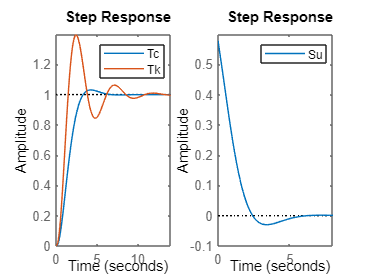

figure(2)
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend

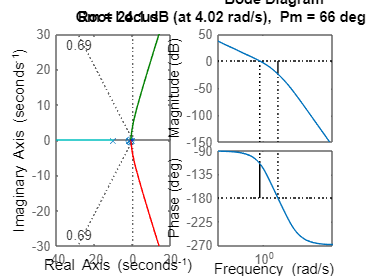

figure(3)
subplot(121),rlocus(GsC),sgrid(Zeta,0)
subplot(122),margin(GsC)

# **Ejercicio #2**

Para el **sistema Gs= 13/(((s+1)*(s+4)*(s+10))) **

diseñar un compensador para que el sistema tenga **un ****Mp****<25% y un ****ts****<4/3s ****Ep****<=0.2**

%Mp? 25%	Ts? 4/3	 Ep=0.2
clc
clear
close all
s=tf('s');
Gs=13/(((s+1)*(s+4)*(s+10)))

Gs =
 
             13
  ------------------------
  s^3 + 15 s^2 + 54 s + 40
 
Continuous-time transfer function.



%Gs=13/((s*(s+1)*(s+4)*(s+10)));
Tk=feedback(Gs,1)

Tk =
 
             13
  ------------------------
  s^3 + 15 s^2 + 54 s + 53
 
Continuous-time transfer function.



ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(Tk,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.67e+00     1.00e+00       1.67e+00         5.99e-01    
 -3.10e+00     1.00e+00       3.10e+00         3.22e-01    
 -1.02e+01     1.00e+00       1.02e+01         9.78e-02    


Resultados =     '
     Ts(2.00)=2.9062
     Tr=1.6034
     Mp=0.0000
     Tp=6.5919
     Tao=0.6318
     ValorF=0.2453
     '


ans = 2.9062

figure(1)
step(Gs,Tk),legend

%% Calcular polos deseados y posicion
clc
close all
Mp=0.24; Ts=4/3;
Sigma=-log(ProcentajeCriterioTs)/Ts

Sigma = 2.9340

Zeta=-log(Mp)/(sqrt(log(Mp)^2+pi^2))

Zeta = 0.4136

Wn=Sigma/Zeta

Wn = 7.0940

Wd=Wn*sqrt(1-Zeta^2)

Wd = 6.4588


figure(2)
subplot(221),rlocus(Gs),sgrid(Zeta,0)
subplot(223),nyquist(Gs)
subplot(122),margin(Gs)
%% 

[C]=LeadLagLGR(Gs,Sigma,Wd,5,0,0,1)

Red adelanta-atraso

C =
 
  60.023 (s+3.833) (s+0.2934)
  ---------------------------
     (s+13.13) (s+0.3349)
 
Continuous-time zero/pole/gain model.



%% 
clc
close all
%C=(4.5866*(s+3))/((s+14))
%C=23.603*(s+5.253)/(s+12.85)
GsC=C*Gs;
Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.98e-01                 1.00e+00       2.98e-01         3.36e+00    
 -3.79e+00                 1.00e+00       3.79e+00         2.64e-01    
 -2.95e+00 + 6.47e+00i     4.15e-01       7.11e+00         3.39e-01    
 -2.95e+00 - 6.47e+00i     4.15e-01       7.11e+00         3.39e-01    
 -1.85e+01                 1.00e+00       1.85e+01         5.41e-02    


Resultados =     '
     Ts(2.00)=1.6092
     Tr=0.2278
     Mp=23.0138
     Tp=0.5484
     Tao=0.3498
     ValorF=0.8330
     '


ans = 1.6092

ErroEpEvEa(GsC)

ans = 0.1670

figure(2)
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend
figure(3)
subplot(121),rlocus(GsC),sgrid(Zeta,0)
subplot(122),margin(GsC)

# **EJERCICIO # 3**

Para el **sistema Gs=2.5/((0.25*s^2+s)) **

diseñar un compensador para que el sistema tenga Kv>=50

%Kv>=50;
clc
clear
close all
s=tf('s');
Gs=2.5/((0.25*s^2+s)) %Funcion de transferencia de el sistema

Gs =
 
      2.5
  ------------
  0.25 s^2 + s
 
Continuous-time transfer function.



%Gs=13/((s*(s+1)*(s+4)*(s+10)));
Tk=feedback(Gs,1) %sistema retroalimentado

Tk =
 
         2.5
  ------------------
  0.25 s^2 + s + 2.5
 
Continuous-time transfer function.



ProcentajeCriterioTs=0.02; %Criterio de el 2% para el tiempo de establecimiento
CriterioRiso=[0.10 0.90];
ParametroSys(Tk,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.00e+00 + 2.45e+00i     6.32e-01       3.16e+00         5.00e-01    
 -2.00e+00 - 2.45e+00i     6.32e-01       3.16e+00         5.00e-01    


Resultados =     '
     Ts(2.00)=1.8951
     Tr=0.6124
     Mp=7.6893
     Tp=1.2894
     Tao=0.4120
     ValorF=1.0000
     '


ans = 1.8951

[Ep,Ev,Ea]=ErroEpEvEa(Gs)

Ep = 0

Ev = 0.4000

Ea = Inf

Kv=1/Ev

Kv = 2.5000

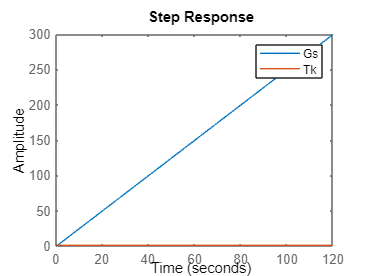

figure(1)
step(Gs,Tk),legend


%% Calcular polos deseados y posicion
clc
close all
Sx=pole(Tk)

Sx =   -2.0000 + 2.4495i
  -2.0000 - 2.4495i


Sigma=-real(Sx(1))

Sigma = 2

Wd=imag(Sx(1))

Wd = 2.4495

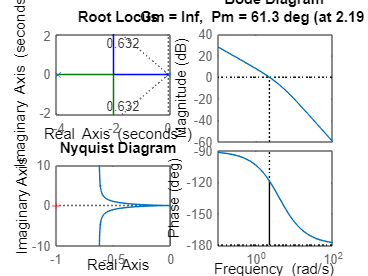


Zeta=Sigma/(sqrt(Sigma^2+Wd^2));
figure(2)
subplot(221),rlocus(Gs),sgrid(Zeta,0)
subplot(223),nyquist(Gs)
subplot(122),margin(Gs)



[C]=LeadLagLGR(Gs,Sigma,Wd,0,50,0,3)

s =
 
  s
 
Continuous-time transfer function.



Beta = 20

C =
 
  1.0382 (s+0.2)
  --------------
     (s+0.01)
 
Continuous-time zero/pole/gain model.



%% 
clc
close all
%C=(4.5866*(s+3))/((s+14))
%C=23.603*(s+5.253)/(s+12.85)
%C=2.2*(s+0.05)/(s+0.015)
%C=(0.9418*(s+0.204))/((s+0.009325))
GsC=C*Gs;
Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.16e-01                 1.00e+00       2.16e-01         4.62e+00    
 -1.90e+00 + 2.45e+00i     6.12e-01       3.10e+00         5.27e-01    
 -1.90e+00 - 2.45e+00i     6.12e-01       3.10e+00         5.27e-01    


Resultados =     '
     Ts(2.00)=6.8728
     Tr=0.5480
     Mp=16.2753
     Tp=1.2624
     Tao=1.4941
     ValorF=1.0000
     '


ans = 6.8728

[Ep,Ev,Ea]=ErroEpEvEa(GsC)

Ep = 0

Ev = 0.0193

Ea = Inf

Kv=1/Ev

Kv = 51.9118

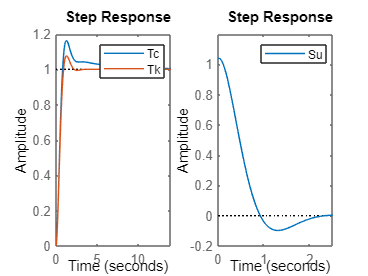

figure(2)
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend

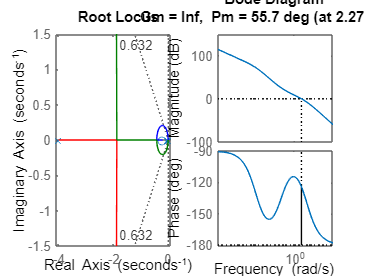

figure(3)
subplot(121),rlocus(GsC) ,sgrid(Zeta,0)
subplot(122),margin(GsC)

%Ejercicio 2 Atraso